clear all
close all
clc

# Spr2023 Final Exam

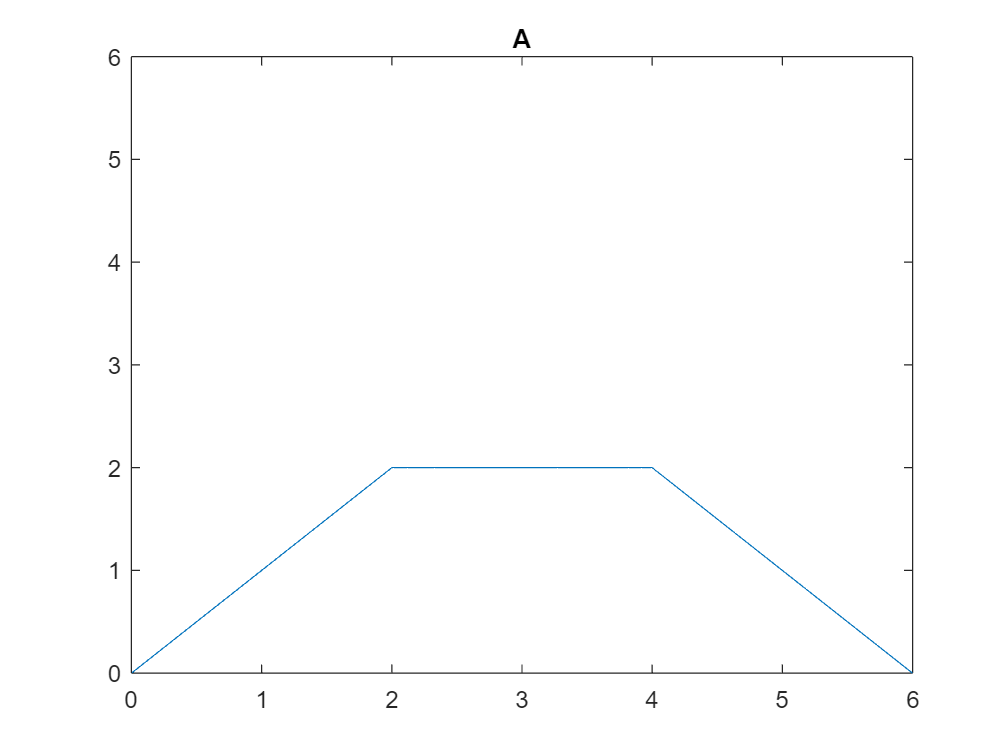

$$ans = t-\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)+\mathrm{heaviside}\left(t-6\right)\,\left(t-6\right)$$

% a = y3t
syms t
xt = heaviside(t) - heaviside(t-4);
ht = heaviside(t) - heaviside(t-2);
myconvolve(xt,ht,'A',6,6)

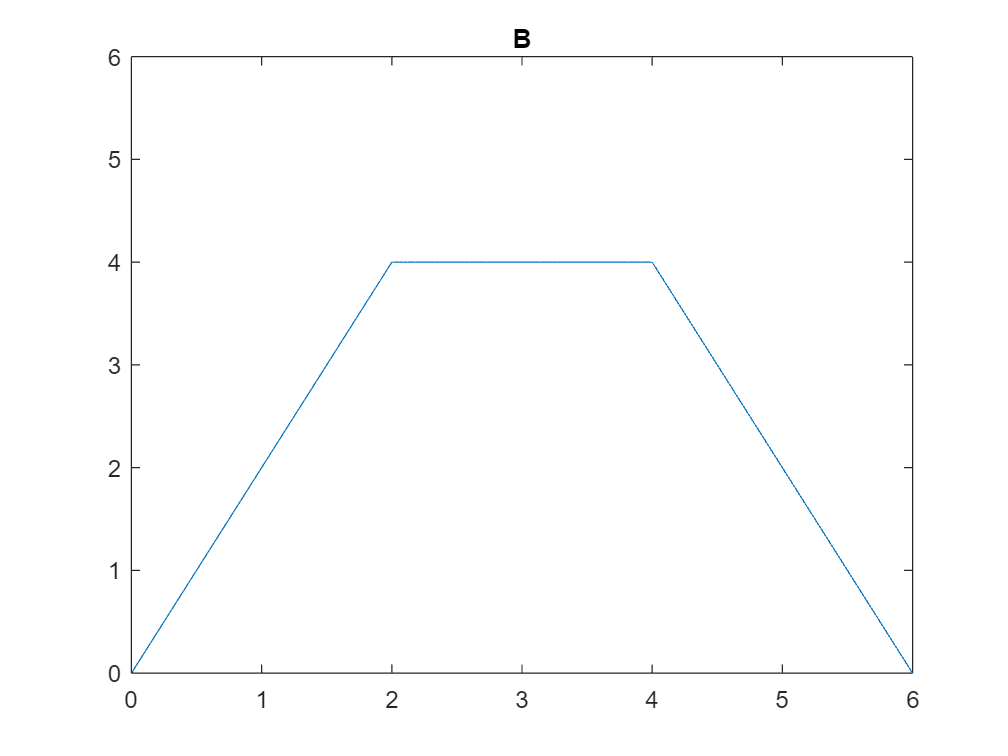

$$ans = 2\,t-2\,\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-2\,\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)+2\,\mathrm{heaviside}\left(t-6\right)\,\left(t-6\right)$$


% b = y2t
syms t
xt = heaviside(t) - heaviside(t-4);
ht = 2*(heaviside(t) - heaviside(t-2));
myconvolve(xt,ht,'B',6,6)

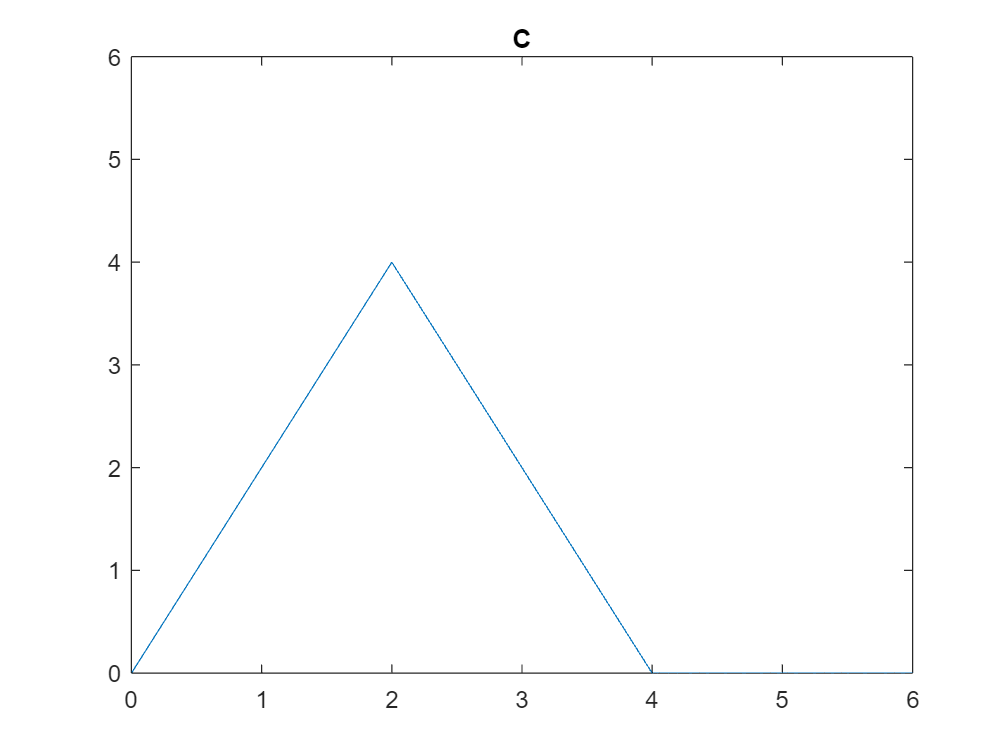

$$ans = 2\,t-4\,\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)+2\,\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)$$


% c = y1t
syms t
xt = (heaviside(t) - heaviside(t-2))*.5;
ht = 4*(heaviside(t) - heaviside(t-2));
myconvolve(xt,ht,'C',6,6)

# Spr2023 Exam 2

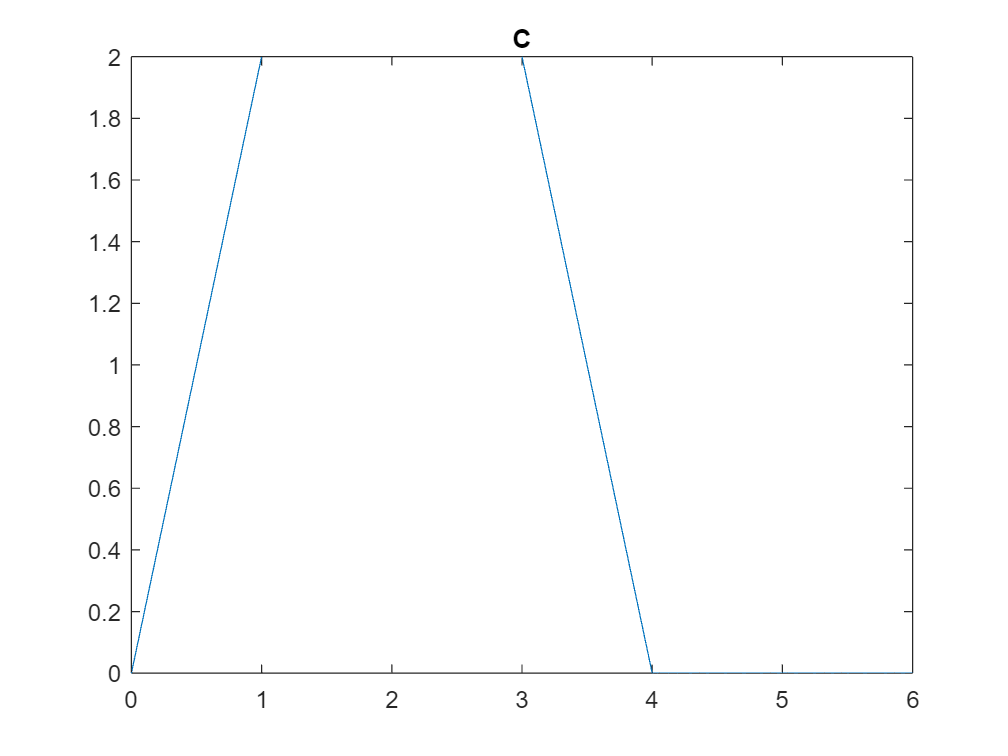

syms t
xt = 2*heaviside(t)-2*heaviside(t-1);
ht = t*heaviside(t)-(t-1)*heaviside(t-1);
ylim([0 2])
hold off

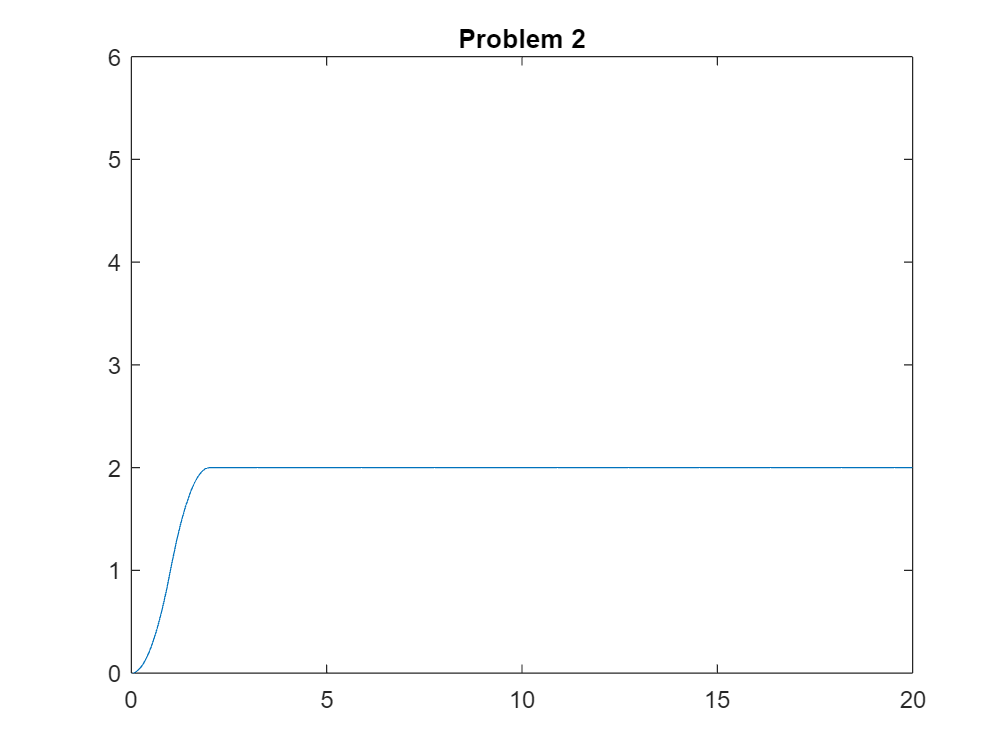

$$eq = \mathrm{heaviside}\left(t-2\right)\,{\left(t-2\right)}^{2}-2\,\mathrm{heaviside}\left(t-1\right)\,{\left(t-1\right)}^{2}+t^{2}$$

eq = myconvolve(xt,ht,'Problem 2',20,6)

# Spr2022 Exam 2

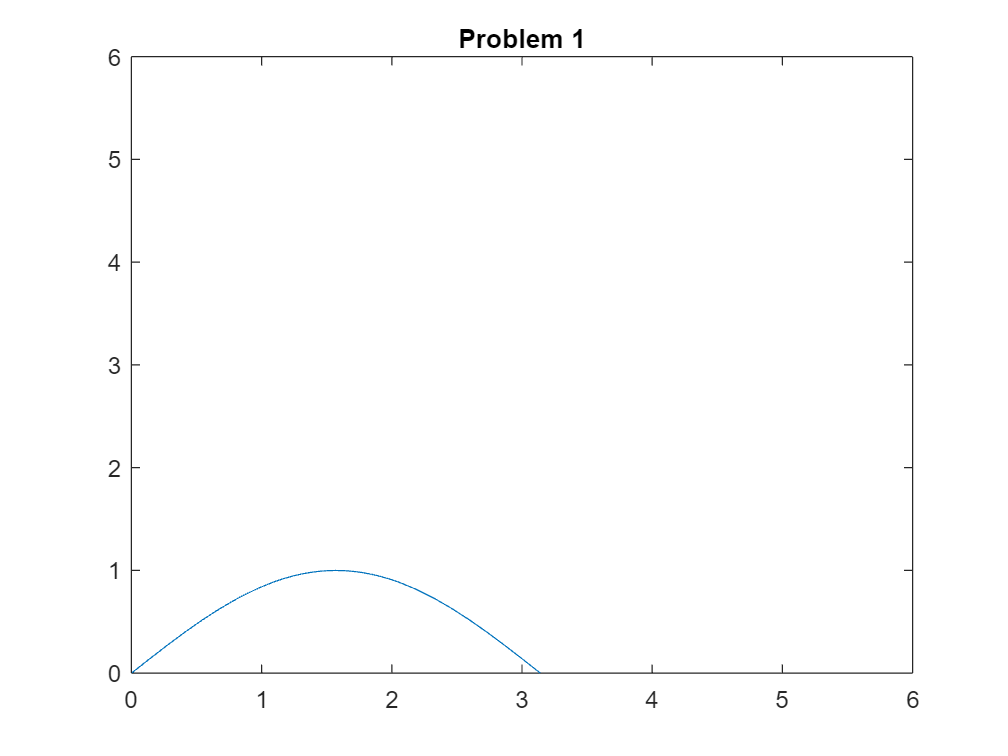

$$eq = \sin\left(t\right)-2\,\sin\left(t\right)\,\mathrm{heaviside}\left(t-2\,\pi \right)+\sin\left(t\right)\,\mathrm{heaviside}\left(t-4\,\pi \right)$$

% Problem 1
syms t
xt = cos(t)*heaviside(t)-cos(t)*heaviside(t-2*pi);
ht = heaviside(t)-heaviside(t-2*pi);
eq = myconvolve(xt,ht,'Problem 1',6,6)

% Problem 2
p1 = -100 + 500*j;
p2 = -100 - 500*j;
transfunc = tfpoles(p1,p2,1,'lp')

transfunc =
 
         260000
  --------------------
  s^2 + 200 s + 260000
 
Continuous-time transfer function.



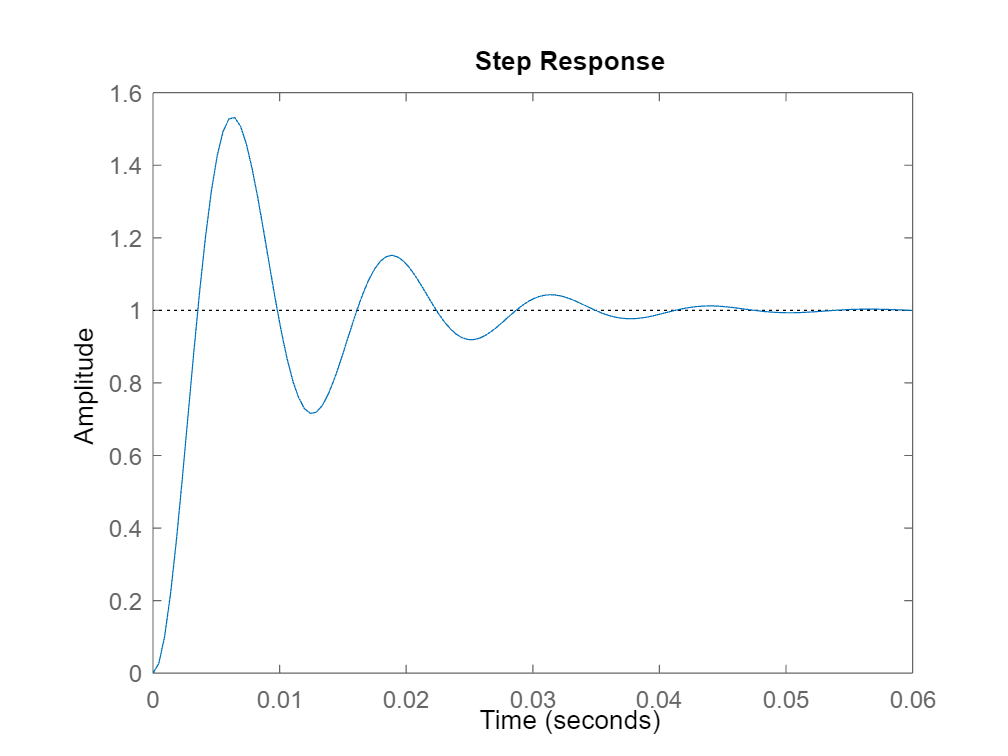

stepplot(transfunc)

# Fal2021 Exam 2

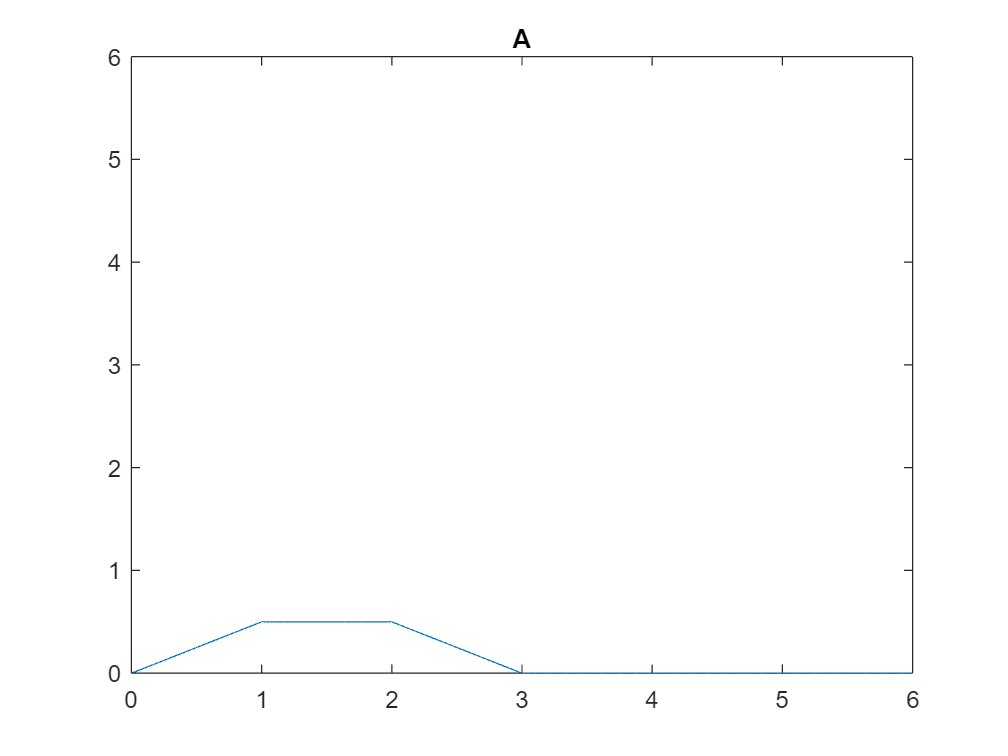

$$eq = \frac{t}{2}-\frac{\mathrm{heaviside}\left(t-1\right)\,\left(t-1\right)}{2}-\frac{\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)}{2}+\frac{\mathrm{heaviside}\left(t-3\right)\,\left(t-3\right)}{2}$$

% Problem 2
syms t
xt = heaviside(t) - heaviside(t-1);
ht = .5*(heaviside(t) - heaviside(t-2));
eq = myconvolve(xt,ht,'A',6,6)

% Problem 3
syms t s k b m 
Zl = s/k;
Zr = 1/b;
Zc = 1/(m*s);
Zrl = (1/Zl+1/Zr)^-1;
% circuit representation 

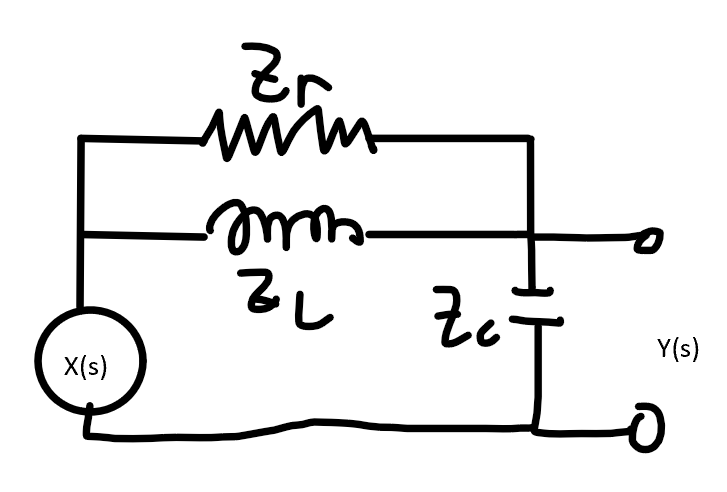

% a

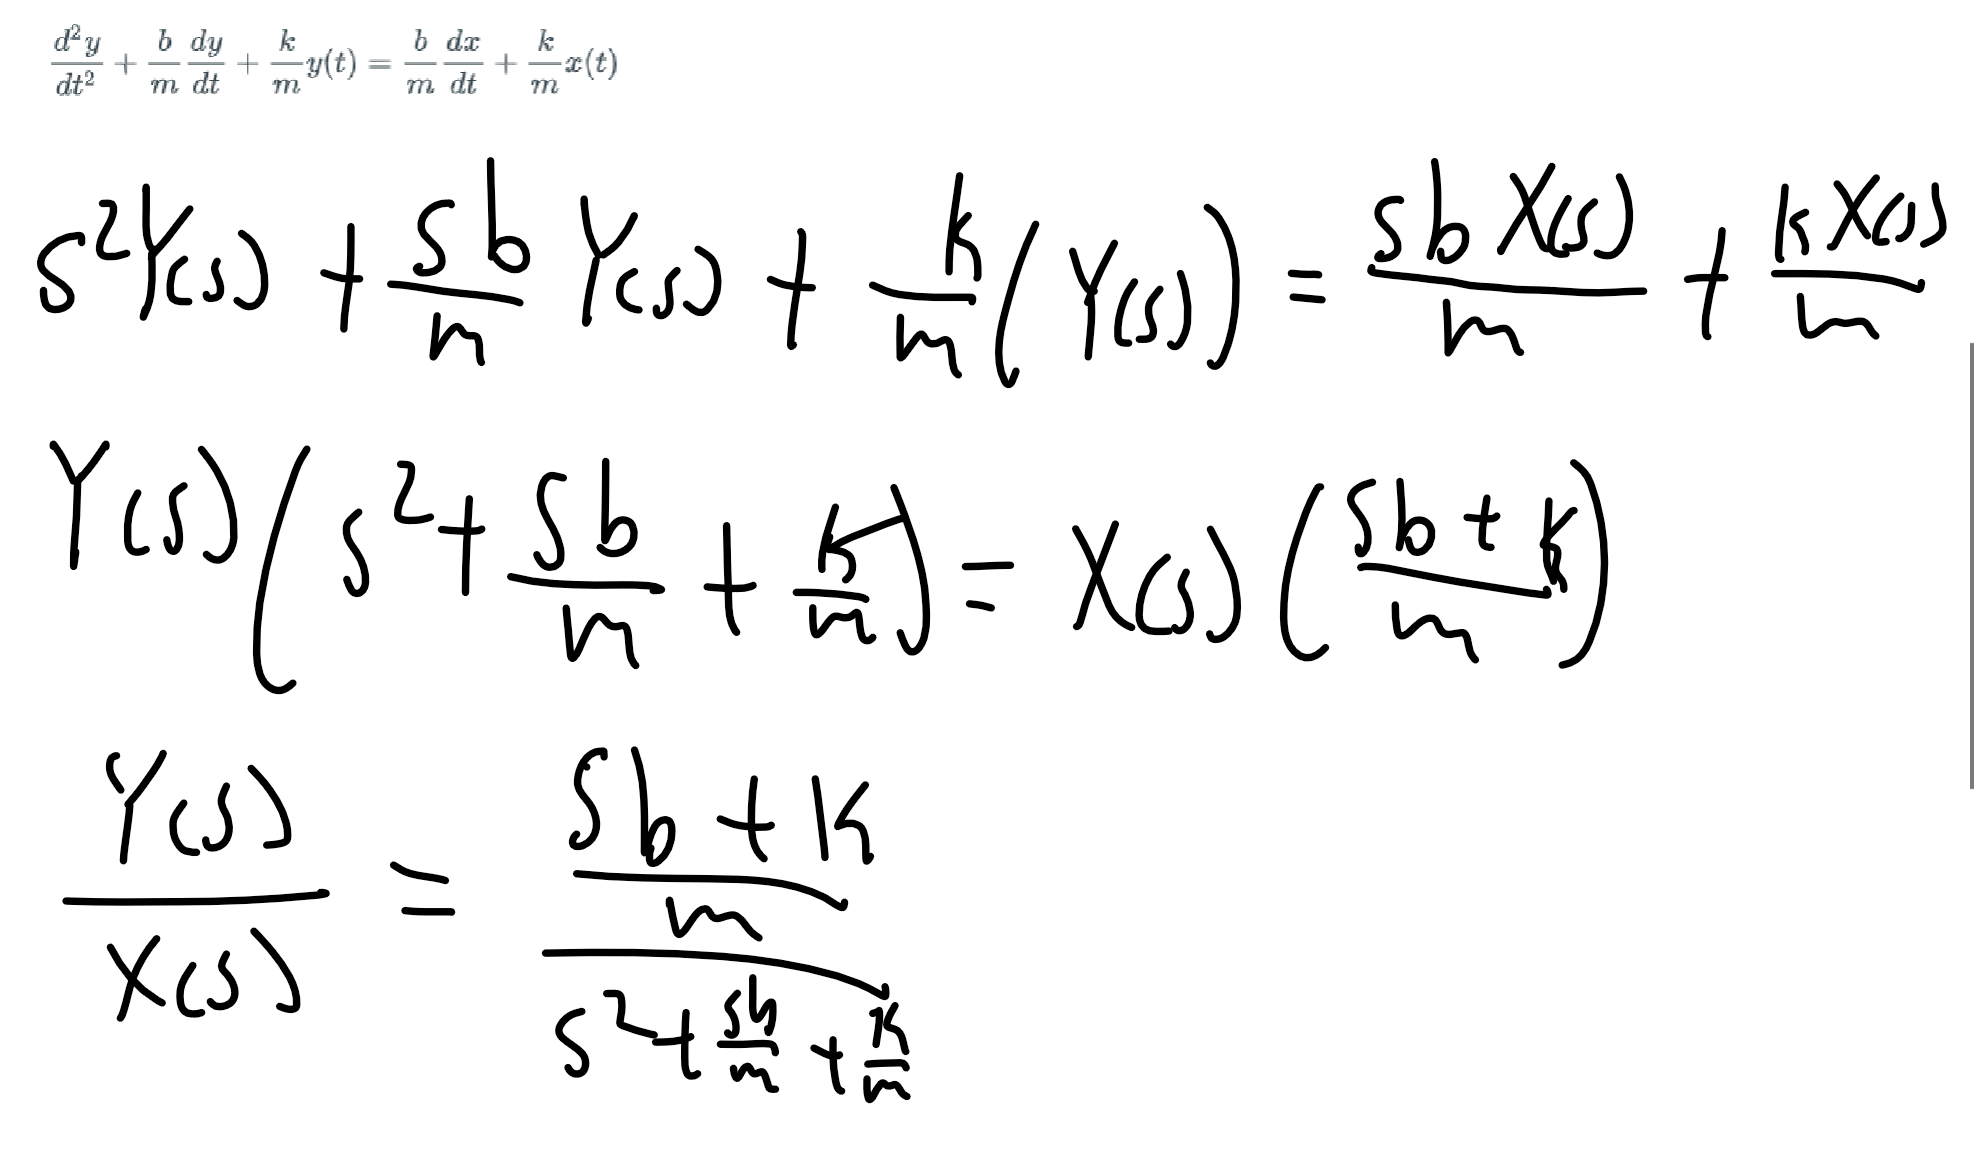

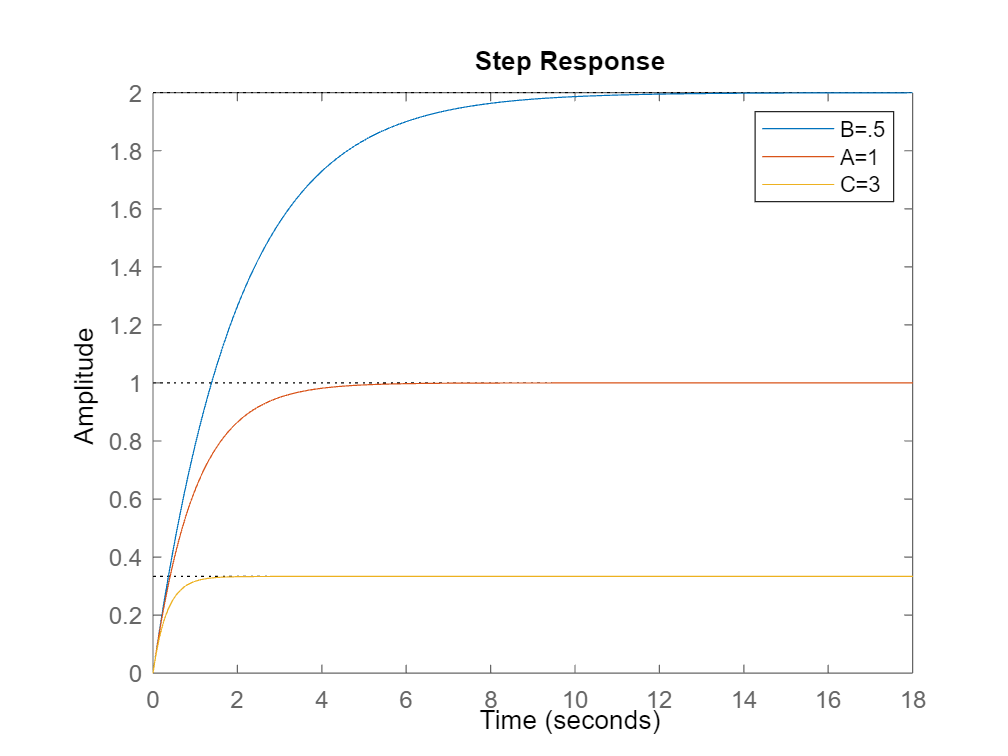

% b 
% low pass filter as the limit as w approaches infinity reaches zero so at
% really high frequencies the filter will spit out smaller and smaller
% values when the limit as w approaches 0 is simply a gain of 1 which we
% assume this system has

% finding transfer function
Vx = 1;
syms Vy I1 I2
eq1 = I1==I2;
eq2 = I1==(Vx-Vy)/(Zrl);
eq3 = I2==Vy/Zc;
eqs = [eq1 eq2 eq3];
ansmat = [Vy I1 I2];
sol = solve(eqs,ansmat);
Hs = sol.Vy;

% c assumed transfunc if k = 0;
Hs_assumed=simplify(subs(Hs,k,0));
Hs_half = totf(subs(subs(Hs_assumed,m,1),b,2));
Hs_one = totf(subs(subs(Hs_assumed,m,1),b,1));
Hs_three = totf(subs(subs(Hs_assumed,m,3),b,1));
stepplot(Hs_half);
hold on
stepplot(Hs_one);
hold on
stepplot(Hs_three);
hold on
legend('B=.5','A=1','C=3')
hold off

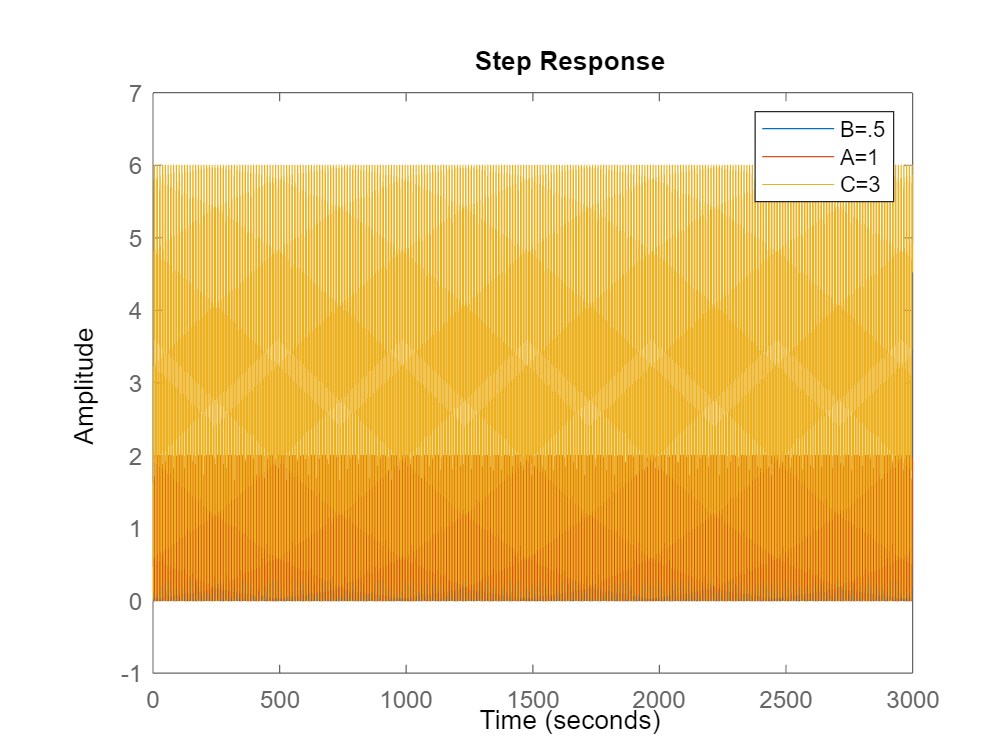


% d assumed transfunc if b = 0;
Hs_assumed=simplify(subs(Hs,b,0));
Hs_half2 = totf(subs(subs(Hs_assumed,m,1),k,.5));

Hs_one2 = totf(subs(subs(Hs_assumed,m,1),k,1));
Hs_three2 = totf(subs(subs(Hs_assumed,m,1),k,3));
stepplot(Hs_half2)
hold on
stepplot(Hs_one2)
hold on
stepplot(Hs_three2)
hold on
legend('B=.5','A=1','C=3')
hold off

# Convolution function

function [pl] = myconvolve(xt,ht,string,x_lim,y_lim)
    pl = ilaplace(laplace(xt)*laplace(ht));
    fplot(pl,[0 x_lim]);
    ylim([0,y_lim])
    title(string)
    hold off
end

# Finding Transfer Function With Poles

function[Hs]=tfpoles(pole1,pole2,gain,string)
    syms A s
    eq1 = A*gain/((s-pole1)*(s-pole2));
    if string =='lp' 
        eq = limit(eq1,s,0,'right')==1;
        sol = double(solve(eq,A));
        transf = subs(eq1,A,sol);
    
    elseif string =='hp'
     eq = limit(eq1,s,inf,'left')==1;
        sol = double(solve(eq,A));
        transf = subs(eq1,A,sol);
    else
        return
    end
    [n, d]=numden(transf);
    coeffs_n=fliplr(double(coeffs(n,'All')));
    coeffs_d=fliplr(double(coeffs(d,'All')));
    Hs=tf(coeffs_n,coeffs_d);
    return
end

# Converting From Transfer Function From Solve To Transfer Function Data Type

function[mytransf]=totf(transf)    
    [n, d]=numden(transf);
    coeffs_n=fliplr(double(coeffs(n,'All')));
    coeffs_d=fliplr(double(coeffs(d,'All')));
    mytransf=tf(coeffs_n,coeffs_d);
    return
end